# Constructability-aware Physics-Informed GNN for Rebar Optimization Design in Concrete Beams (CPyRO-GraphNet-Beams)

This figure below shows the DL architecture and the Loss function of the model.

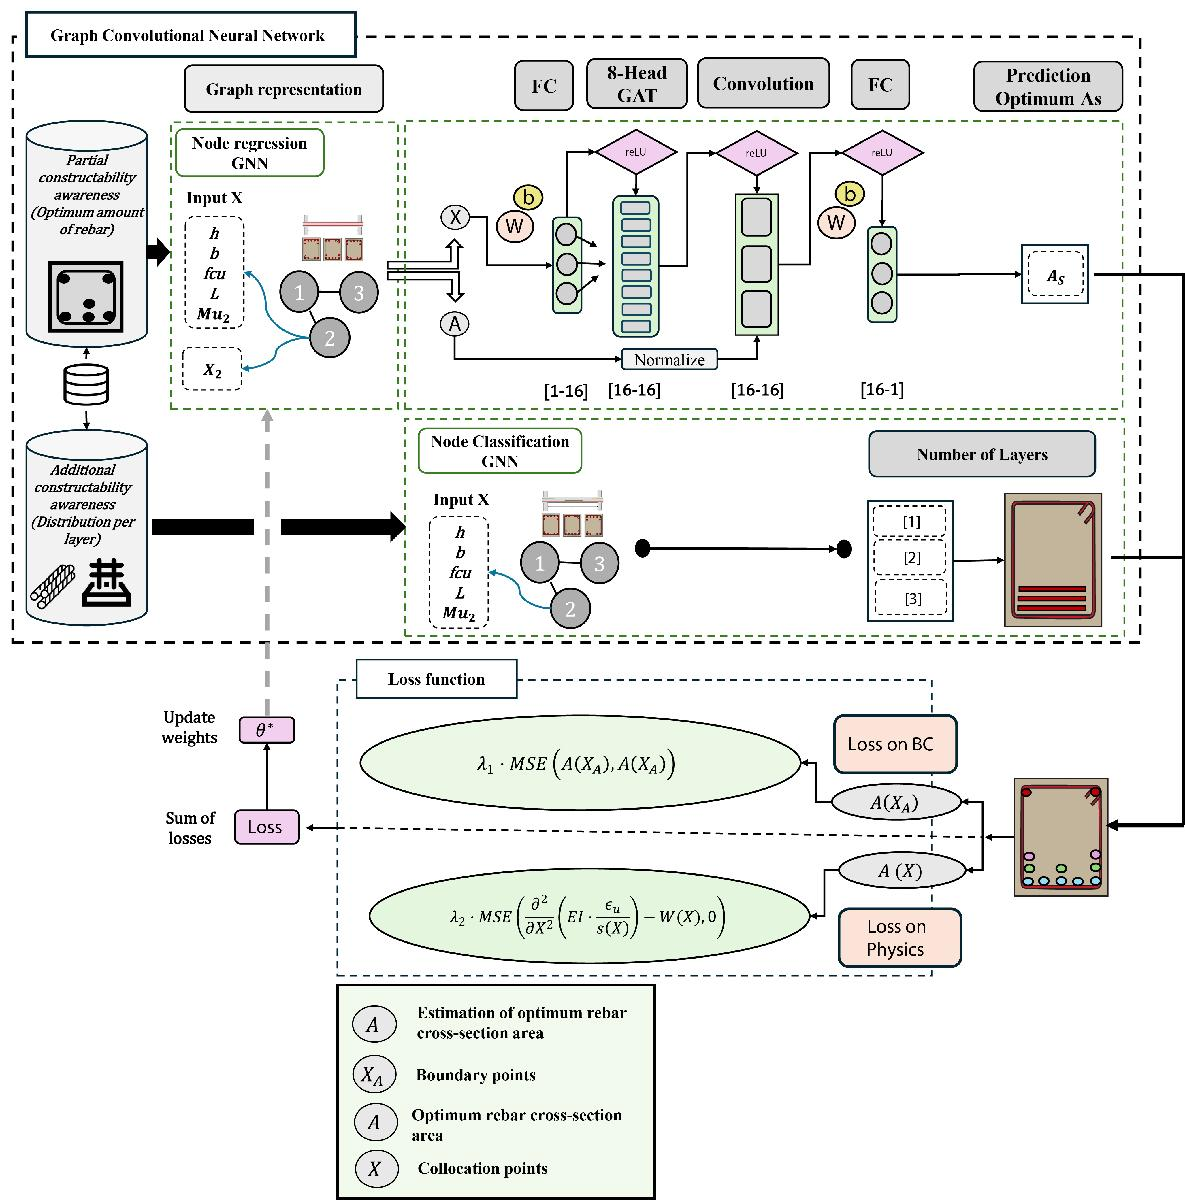

Note: Training this network is a computationally intensive task. To make the example run quicker, this example skips the training step and loads a pretrained network. To instead train the network, set the `doTraining` variable to `true`.

doTraining = false;

## Load Data

Give the path of the folder where the data is stored. Adjust it to your own path. 

A=importdata('Data_1LOT_HK_Nb_Db_Simple_4000.xlsx');
DR=A.data;
numObservations=size(DR,1);


Adjust the follwing variable "subsize" if not all data is required to be read.

subsize=numObservations;
idxSubData=ceil(rand(subsize,1)*numObservations);
DR=DR(idxSubData,:);
numObservations=length(DR(:,1));

View the data.

DR

The data is an array of 27 columns. The first 7 columns represent the input features of the nework. b, h, fcu, L, Mur, Mum, Mul. The next two columns are the magnitudes of the distributed loads in N/mm. Then, the rest of columns are the targets (optimum rebar design features, number of rebars and the diameter sizes).

## Prepare Data for Training

Extract and concatenate the node features.


%% Data points to enforce BC

dL = 100;
i = 0;
for j =1:numObservations
    As9(j,:)=[sum(DR(j,10:12).*DR(j,19:21).^2*pi/4),...
              sum(DR(j,13:15).*DR(j,22:24).^2*pi/4),...
              sum(DR(j,16:18).*DR(j,25:27).^2*pi/4)];

    A13=As9(j,:)';
    if sum([A13']) > 0 % Consider only samples with feasible solutions
        i = i + 1;

        XNL(i,:)=DR(i,1:7);
        fcu(1,i)=DR(j,3);
        b(1,i)=DR(j,1);
        h(1,i)=DR(j,2);
        L(1,i)=DR(j,4);
        Mul(1,i)=abs(DR(j,5));
        Mum(1,i)=DR(j,6);
        Mur(1,i)=abs(DR(j,7));
        Wleft=DR(j,8);
        Wright=DR(j,9);

        Wx(:,i) = [Wleft ; Wright];
        
        Ac = b(1,i) * h(1,i);
        Ic=b(1,i)*h(1,i)^3/12;
        Ec=(3.46*sqrt(fcu(1,i))+3.21)*1e3;

        EI(1,i)=Ec*Ic;

        [R,U,V,M]=MSFSFEMBeams(L(1,i),Ac,Ic,Ec,[0,L(1,i)],[Wleft,Wright],dL,[0,L(1,i)],0);
        [Mmid,mp]=max(M(1,:));
        xMmid = (mp-1) * dL ;

        %% Data points to enforce BC (rebar cross-section area quantities)

        u1L(:,i)=A13;

        %% Data points to enforce BC (rebar cross-section area quantities)
        x0L(:,i)=[10,xMmid,L(1,i)-10]';
    end
end

Get the indeces of training, validation and testing data with function trainingPartitions attahced in the Function appendix.

numObservations = size(EI,2);

[idxTrain,idxValidation,idxTest] = trainingPartitions(numObservations,[0.7 0.15 0.15]);
nTrain=length(idxTrain);
nValidation=length(idxValidation);
nTest=length(idxTest);

% Prepare spatial data for training PINN

X = x0L;

domainCollocPointsXTrain = X(:,idxTrain);
domainCollocPointsXVal = X(:,idxValidation);
domainCollocPointsXTest = X(:,idxTest);

numCollocationPoints = size(X,1);

dataWTrain = Wx(:,idxTrain);
dataWValidation = Wx(:,idxValidation);
dataWTest = Wx(:,idxTest);

dataLTrain = L(1,idxTrain);
dataLValidation = L(1,idxValidation);
dataLTest = L(1,idxTest);

dataEITrain = EI(1,idxTrain);
dataEIValidation = EI(1,idxValidation);
dataEITest = EI(1,idxTest);

databTrain = b(1,idxTrain);
databValidation = b(1,idxValidation);
databTest = b(1,idxTest);

datahTrain = h(1,idxTrain);
datahValidation = h(1,idxValidation);
datahTest = h(1,idxTest);

datafcuTrain = fcu(1,idxTrain);
datafcuValidation = fcu(1,idxValidation);
datafcuTest = fcu(1,idxTest);

Mulmr=[Mul(1,:);
       Mum(1,:);
       Mur(1,:)];
        
MulmrTrain=Mulmr(:,idxTrain);
MulmrValidation=Mulmr(:,idxValidation);
MulmrTest=Mulmr(:,idxTest);

u0BC1 = u1L';

nodesAb1to3=[u0BC1];

u0BC1Train = u1L(:,idxTrain)';

u0BC1Test = u1L(:,idxTest)';

% Prepare Training/Validation/Test data - Convertion to DL arrays
% Training data
BCU1Train = dlarray(u0BC1Train,"BC");

domainCollocPointsXTrain = dlarray(domainCollocPointsXTrain , "CB");

dataWTrain = dlarray(dataWTrain , "BC");
dataLTrain = dlarray(dataLTrain , "BC");
dataEITrain = dlarray(dataEITrain , "BC");
databTrain = dlarray(databTrain , "BC");
datahTrain = dlarray(datahTrain , "BC");
datafcuTrain = dlarray(datafcuTrain , "BC");
MulmrTrain = dlarray(MulmrTrain , "BC");

pdeCoeffsTrain=dlarray([dataWTrain,dataLTrain,dataEITrain,databTrain,...
                        datahTrain,datafcuTrain,MulmrTrain],"BC");

% Validation data

domainCollocPointsXVal = dlarray(domainCollocPointsXVal , "CB");

% Test data
BCU1Test = dlarray(u0BC1Test,"BC");

domainCollocPointsXTest = dlarray(domainCollocPointsXTest , "CB");

## **Define graph connectivity**

% Node connectivity
elements=[2 1 ;
          1 3];

% Adjacency matrix
numNodesGNN=3;
% Adjancency matrix
adjacency = zeros(numNodesGNN);
for i = 1:size(elements,2)
    % The following logic specifies each node in an element is connected to
    % each other node in that element.
    nodesForElement = elements(:,i);
    for node = nodesForElement
        adjacency(nodesForElement,node) = 1;
    end
end

adjacency=repmat(adjacency,[1,1,numObservations]);


Prepare the data related to the coordinates of the BC points

% X coordinates of BC points
XBC=zeros(numObservations,numNodesGNN,numNodesGNN);
for i=1:numObservations
    for j=1:numNodesGNN
        XBC(i,j,j)=X(j,i);
    end
end
XBC = double(permute(XBC, [2 3 1]));

View the size of the label data.

size(XBC)

Further proceed to partition the data with the random indeces previously generated.


% node adjacency data
adjacencyDataTrain = adjacency(:,:,idxTrain);
adjacencyDataValidation = adjacency(:,:,idxValidation);
adjacencyDataTest = adjacency(:,:,idxTest);

% feature data
XBCTrain1 = XBC(:,:,idxTrain);
XBCValidation1 = XBC(:,:,idxValidation);
XBCTest1 = XBC(:,:,idxTest);

% target data
AsDataTrain = nodesAb1to3(idxTrain,:);
AsDataValidation = nodesAb1to3(idxValidation,:);
AsDataTest = nodesAb1to3(idxTest,:);

% Train partition
[ATrain,XTrain1,labelsTrain] = preprocessData(adjacencyDataTrain,XBCTrain1,AsDataTrain);

% Validation partition
[AValidation,XValidation1,labelsValidation] = preprocessData(adjacencyDataValidation,XBCValidation1,AsDataValidation);

XTrain=[XTrain1];
XValidation=[XValidation1];

% Gather data into one single variable and normalize it with standard normalization 
[XTrainPIGNN,XValidationPIGNN,XTestPIGNN,meanXNL,sigsqXNL]=dataTrainNLClass(XNL,idxTrain,...
                        idxValidation,idxTest,adjacency,numNodesGNN,AsDataTrain,...
                        AsDataValidation,AsDataTest);


## **Define model for PIGNN**


pignn = struct;
numHiddenFeatureMaps1 = 16;
numHiddenFeatureMaps2 = 16;

numInputFeatures = size(XTrainPIGNN,2);

sz = [numInputFeatures numHiddenFeatureMaps1];
numOut = numHiddenFeatureMaps1;
numIn = numInputFeatures;

pignn.Embed.Weights = initializeGlorot(sz,numOut,numIn,"double");
pignn.Embed.b = initializeZeros([1,numOut]);

% Graph attention operation
numHeads=struct;
numHeads.attn1=8;

% First attention layer
sz = [numHiddenFeatureMaps1 numHiddenFeatureMaps1];
numOut = numHiddenFeatureMaps1;
numIn = numHiddenFeatureMaps1;

pignn.attn1.Weights.linearWeights = initializeGlorot(sz,numOut,numIn,'double');
pignn.attn1.Weights.attentionWeights = initializeGlorot([numOut 2],1,2*numOut,'double');

% Multiply operation - Convolutional Layer

sz = [numHiddenFeatureMaps1 numHiddenFeatureMaps2];
numOut = numHiddenFeatureMaps2;
numIn = numHiddenFeatureMaps1;

pignn.mult1.Weights = initializeGlorot(sz,numOut,numIn,"double");

% Fully Connected Layer

numClasses = 1;
sz = [numHiddenFeatureMaps2 numClasses];
numOut = numClasses;
numIn = numHiddenFeatureMaps2;

pignn.Decoder.Weights = initializeGlorot(sz,numOut,numIn,"double");
pignn.Decoder.b = initializeZeros([1,numOut]);

## **Specify Training Options**

%% Training parameters
nheadsparamnNLclass=load("Constructability_Awareness_GNN/nHead_nLay_GNN_4000.mat");
paramNLclass=load("Constructability_Awareness_GNN/nLay_GNN_4000.mat");

paramNL=paramNLclass.parameters;
nheadsParamNL=nheadsparamnNLclass.numHeads;

numEpochs = 80;
miniBatchSize = numCollocationPoints;
initialLearnRate = 0.01;
learnRateDecay = 0.001;

validationFrequency = 5;

XTrain = dlarray(XTrain);
XValidation = dlarray(XValidation);
TTrain = labelsTrain;
TValidation = labelsValidation;


## **Train model**

Train the model using a custom training loop.


%% Train PINN
if doTraining
    % Initialize the parameters for Adam optimizer.
    averageGrad = [];
    averageSqGrad = [];
    
    monitor = trainingProgressMonitor(Metrics=["TrainingLoss","ValidationLoss"], ...
                                      Info="Epoch", ...
                                      XLabel="Iteration");
    groupSubPlot(monitor,"Loss",["TrainingLoss","ValidationLoss"])
     Call the function containing the architecture of the pretrained

    % GNN model for constructability awareness- pass the loaded parameters
    NLTrain = modelNL(paramNL,XTrainPIGNN,ATrain,nheadsParamNL);
    epoch = 0;
    learningRate = initialLearnRate;
    itervalid=0;
    while epoch < numEpochs && ~monitor.Stop
        epoch = epoch + 1;
        
        % Evaluate the model loss and gradients using dlfeval.
        [loss(epoch),gradients] = dlfeval(@modelLossPIGNN1GAT1Conv1fc,pignn,...
            XTrain,ATrain,TTrain,XTrainPIGNN,pdeCoeffsTrain,numHeads,NLTrain);
    
        % Update the network parameters using the adamupdate function.
        [pignn,averageGrad,averageSqGrad] = ...
            adamupdate(pignn,gradients,averageGrad, ...
                       averageSqGrad,epoch,learningRate);
        
        % Update the training progress monitor.
        recordMetrics(monitor,epoch,TrainingLoss=loss(epoch));
        updateInfo(monitor,Epoch=epoch + " of " + numEpochs);
        
        % Display the validation metrics.
        if epoch == 1 || mod(epoch,validationFrequency) == 0
            itervalid = itervalid +1;
            YValidation = model1GAT1Conv1fc(pignn,XValidationPIGNN,AValidation,numHeads);
            
            lossValidation(itervalid) = mse(YValidation,TValidation,DataFormat="BC");
            % Record the validation loss.
            recordMetrics(monitor,epoch,ValidationLoss=lossValidation(itervalid));
        end
    
        % Update learning rate.
        learningRate = initialLearnRate / (1+learnRateDecay*epoch);
    
        monitor.Progress = 100 * epoch/numEpochs;
    end      
    
    save('PIGCNN_As_Section_4000',"pignn")
    save('nHeads_GAT_PIGNN_As_Section_4000','numHeads')
else
    nheadsparamnGATPIGNN=load("nHeads_GAT_PIGNN_As_Section_4000.mat");
    paramPIGCNN=load("PIGCNN_As_Section_4000.mat");
end

### Define Model Function

Create the function model1GAT1Conv1fc, defined in the Model Function section of the example, which takes as input the model parameters, the input features and adjacency matrix, and the number of nodes per graph, and returns predictions for the labels.

### Define Model Loss Function

Create the function modelLossPIGNN1GAT1Conv1fc, defined in the Model Loss Function section of the example, which takes as input the model parameters, a mini-batch of input features and corresponding adjacency matrix, the number of nodes per graph, and the corresponding encoded targets of the labels, and returns the loss, the gradients of the loss with respect to the learnable parameters, and the model predictions.

## **Test model - **Predict using unseen data

% Get test labels
[ATest,~,labelsTest] = preprocessData(adjacencyDataTest,XBCTest1,AsDataTest);

TTest = labelsTest;
if doTraining
    YTest = model1GAT1Conv1fc(pignn,XTestPIGNN,ATest,numHeads);
else
    YTest = model1GAT1Conv1fc(paramPIGCNN.pignn,XTestPIGNN,ATest,nheadsparamnGATPIGNN.numHeads);
end

Gather test predictions and test labels to analyse performance


mre=[];

YAo1=dlarray([]);
Ypvt1=dlarray([]);
YAo2=dlarray([]);
Ypvt2=dlarray([]);
YAo3=dlarray([]);
Ypvt3=dlarray([]);
for i=1:nTest
    i1=(i-1)*3+1;
    i2=(i)*3;
    
    Aopt1=sum([BCU1Test(1,i)]);
    Apred1=sum([YTest(i1,1)]);

    Aopt2=sum([BCU1Test(2,i)]);
    Apred2=sum([YTest(i1+1,1)]);

    Aopt3=sum([BCU1Test(3,i)]);
    Apred3=sum([YTest(i2,1)]);
    
    % Mean Relative Error
    MRE1=abs(Aopt1-Apred1)/Aopt1;
    MRE2=abs(Aopt2-Apred2)/Aopt2;
    MRE3=abs(Aopt3-Apred3)/Aopt3;

    MREC = extractdata([MRE1,MRE2,MRE3]);

    mre=[mre; MREC'];
    
    % Gather test predictions and test labels
    YAo1=[YAo1; dlarray([BCU1Test(1,i)],"BC")];
    Ypvt1=[Ypvt1; dlarray([YTest(i1,1)],"BC")];

    YAo2=[YAo2; dlarray([BCU1Test(2,i)],"BC")];
    Ypvt2=[Ypvt2; dlarray([YTest(i1+1,1)],"BC")];

    YAo3=[YAo3; dlarray([BCU1Test(3,i)],"BC")];
    Ypvt3=[Ypvt3; dlarray([YTest(i2,1)],"BC")];

end

Compute Regression coefficients for the three main cross-section of each test beam model


% R coefficients
YAo1=extractdata(YAo1);
Ypvt1=extractdata(Ypvt1);
[BT1]=MLR2([[YAo1],[Ypvt1]],0);
YPT1=BT1(1).*[YAo1];

if BT1(1)>1
    BT1(1)=1/BT1(1);
end

YAo2=extractdata(YAo2);
Ypvt2=extractdata(Ypvt2);
[BT2]=MLR2([[YAo2],[Ypvt2]],0);
YPT2=BT2(1).*[YAo2];

if BT2(1)>1
    BT2(1)=1/BT2(1);
end

YAo3=extractdata(YAo3);
Ypvt3=extractdata(Ypvt3);
[BT3]=MLR2([[YAo3],[Ypvt3]],0);
YPT3=BT3(1).*[YAo3];

if BT3(1)>1
    BT3(1)=1/BT3(1);
end

disp('R coefficient')

R coefficient


disp(BT1(1))

    0.8109




disp('R coefficient')

R coefficient


disp(BT2(1))

    0.9502




disp('R coefficient')

R coefficient


disp(BT3(1))

    0.8026



### Regression plots

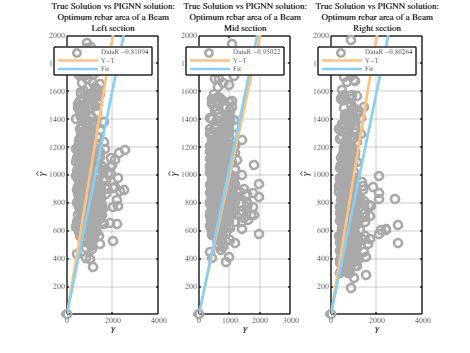


% Define pastel colors
pastel_gray = [0.663,0.663,0.663]; % #D3D3D3 for scatter points
pastel_green = [0.537,0.812,0.941]; % #B5EAD7 for fit line
pastel_orange = [0.992,0.761,0.506]; % #FDC281 for identity line

figure(9)
subplot(1,3,1)
plot([0;YAo1],[0;Ypvt1],'o', 'Color', pastel_gray,'LineWidth',2)
hold on
plot([0;YAo1],[0;YAo1],'-', 'Color', pastel_orange,'LineWidth',2)
hold on
plot([0;YAo1],[0;YPT1],'-', 'Color', pastel_green,'LineWidth',2)
hold on
legend(strcat('Data ','R = ',num2str(BT1(1))),'Y=T','Fit')
xlabel('$Y$',interpreter='latex')
ylabel('$\hat{Y}$',interpreter='latex')
title({strcat('True Solution vs PIGNN ', ' solution:'),'Optimum rebar area of a Beam',...
    'Left section'},interpreter='latex') 
hold on
grid on
axis([[0 4000],[0 2000]])
set(gca, 'Fontname', 'Times New Roman','FontSize',6);


figure(9)
subplot(1,3,2)
plot([0;YAo2],[0;Ypvt2],'o', 'Color', pastel_gray,'LineWidth',2)
hold on
plot([0;YAo2],[0;YAo2],'-', 'Color', pastel_orange,'LineWidth',2)
hold on
plot([0;YAo2],[0;YPT2],'-', 'Color', pastel_green,'LineWidth',2)
hold on
legend(strcat('Data ','R = ',num2str(BT2(1))),'Y=T','Fit')
xlabel('$Y$',interpreter='latex')
ylabel('$\hat{Y}$',interpreter='latex')
title({strcat('True Solution vs PIGNN ', ' solution:'),'Optimum rebar area of a Beam',...
    'Mid section'},interpreter='latex') 
hold on
grid on
axis([[0 3000],[0 2000]])
set(gca, 'Fontname', 'Times New Roman','FontSize',6);

figure(9)
subplot(1,3,3)
plot([0;YAo3],[0;Ypvt3],'o', 'Color', pastel_gray,'LineWidth',2)
hold on
plot([0;YAo3],[0;YAo3],'-', 'Color', pastel_orange,'LineWidth',2)
hold on
plot([0;YAo3],[0;YPT3],'-', 'Color', pastel_green,'LineWidth',2)
hold on
legend(strcat('Data ','R = ',num2str(BT3(1))),'Y=T','Fit')
xlabel('$Y$',interpreter='latex')
ylabel('$\hat{Y}$',interpreter='latex')
title({strcat('True Solution vs PIGNN ', ' solution:'),'Optimum rebar area of a Beam',...
    'Right section'},interpreter='latex') 
hold on
grid on
axis([[0 4000],[0 2000]])
set(gca, 'Fontname', 'Times New Roman','FontSize',6);


lossTest = mse(YTest,TTest,DataFormat="BC");
disp('MSE')

MSE


disp(lossTest)

  1×1 single dlarray

  1.2907e+05



## Model Function

The `model` function takes as inputs the model parameters `parameters`, the feature matrix `X`, the adjacency matrix `A`, the number of nodes per graph `numNodes`, and the number of heads `numHeads`, and returns the predictions and the attention scores.

The function:

- Computes the graph attention at each layer using the `graphAttention` function defined in the Attention Function section of the example.

- Uses ELU nonlinearity, using the `elu` function defined in the ELU Function section of the example as the activation function for the first two layers.

- Employs a residual connection in the hidden layer to aid convergence.

- Uses the `globalAveragePool` function, defined in the Global Average Pool Function section of the example, to perform the readout operation after the final layer.

- Uses the `sigmoid` function to compute the label predictions as independent class probabilities.


function Y = model1GAT1Conv1fc(parameters,X,A,numHeads)

    ANorm = normalizeAdjacency(A);
    
    Z1 = X * parameters.Embed.Weights + parameters.Embed.b;
    
    weights1 = parameters.attn1.Weights;
    numHeadsAttention1 = numHeads.attn1;

    [Z2,~] = graphAttention(Z1,A,weights1,numHeadsAttention1,"cat");
    Z2  = relu(Z2);
    
    Z3 = single(full(ANorm)) * Z2 * double(parameters.mult1.Weights);
    Z3 = relu(Z3);

    Z4 = Z3 * parameters.Decoder.Weights + parameters.Decoder.b;
    Z4 = relu(Z4);

    Y = Z4;
    
end

## Model Loss Function

The `modelLoss` function takes as inputs the model parameters `parameters`, the feature matrix `X`, the adjacency matrix `adjacencyTrain`, the number of nodes per graph `numNodes`, the binary encoded labels `T`, and the number of heads `numHeads`, and returns the gradients of the loss with respect to the model parameters, the corresponding loss, and the model predictions.


function [loss,gradients] = modelLossPIGNN1GAT1Conv1fc(pinn,...
    XTrain,A,TTrain,XTrainNL,pdeCoeffs,numHeads,NL)

    U = model1GAT1Conv1fc(pinn,XTrainNL,A,numHeads);
    
    Es=200e3 ;
    ecu=0.0035;
    Cc=50;
    dvs=10;
    nmodels=size(pdeCoeffs,2);
    
    avLossF = 0;
    for nm = 1: nmodels
        i1=(nm-1)*3+1;
        i2=(nm)*3;
        Xnm=XTrain([i1:i2]',1); % X used for differentiation
        
        W1=pdeCoeffs(1,nm);
        W2=pdeCoeffs(2,nm);
        L=pdeCoeffs(3,nm);
        EI=pdeCoeffs(4,nm);
        b=pdeCoeffs(5,nm);
        h=pdeCoeffs(6,nm);
        fcu=pdeCoeffs(7,nm);
        
        Wx=W1+(W2-W1)/L.*Xnm;
        
        % Compute neural axis for each collocation point (cross-section)
        bp = b-2*Cc-2*dvs;
        
        % Left node
        nlayers1=NL(i1,1);
        if nlayers1==3
            AsLayer11=U(i1,1)*0.6;
            AsLayer21=U(i1,1)*0.3;
            AsLayer31=U(i1,1)*0.2;
        elseif nlayers1==2
            AsLayer11=U(i1,1)*0.7;
            AsLayer21=U(i1,1)*0.3;
            AsLayer31=0;
        elseif nlayers1==1
            AsLayer11=U(i1,1);
            AsLayer21=0;
            AsLayer31=0;
        end

        tw11=(AsLayer11)/bp;
        tw21=AsLayer21/bp;
        tw31=(AsLayer31)/bp;
        
        % Mid node
        nlayers2=NL(i1+1,1);
        if nlayers2==3
            AsLayer12=U(i1+1,1)*0.6;
            AsLayer22=U(i1+1,1)*0.3;
            AsLayer32=U(i1+1,1)*0.2;
        elseif nlayers2==2
            AsLayer12=U(i2-1,1)*0.7;
            AsLayer22=U(i2-1,1)*0.3;
            AsLayer32=0;
        elseif nlayers2==1
            AsLayer12=U(i2-1,1);
            AsLayer22=0;
            AsLayer32=0;
        end

        tw12=(AsLayer12)/bp;
        tw22=AsLayer22/bp;
        tw32=(AsLayer32)/bp;

        % Right node
        nlayers3=NL(i2,1);
        if nlayers3==1
            AsLayer13=U(i2,1);
            AsLayer23=0;
            AsLayer33=0;
        elseif nlayers3==2
            AsLayer13=U(i2,1)*0.7;
            AsLayer23=U(i2,1)*0.3;
            AsLayer33=0;
        elseif nlayers3==3
            AsLayer13=U(i2,1)*0.6;
            AsLayer23=U(i2,1)*0.3;
            AsLayer33=U(i2,1)*0.2;
        end

        tw13=(AsLayer13)/bp;
        tw23=AsLayer23/bp;
        tw33=(AsLayer33)/bp;
        
        % Left cross-section
        tlist1=[tw11,tw21,tw31];
        asb1 = tlist1 .* bp ;
        ast1 = sum(asb1);
        
        [tdistr1]=distrRecBeam3tLayersDLarray(b,h,Cc,tlist1,25);
        
        yi1 = tdistr1(:, 1);
        di1 = 0.5 * h - yi1 ;

        f11 = [asb1(1) .* di1(1), asb1(2) .* di1(2), asb1(3) .* di1(3)] ;
        
        f31 = (0.45 .* b .* fcu) ./ (Es .* ecu) ;
        root1 = sqrt(ast1.^2 + 4 .* f31 .* sum(f11));
        s1  =  (-ast1 + root1 ) ./ (2 .* f31);
        
        % Mid cross-section
        tlist2=[tw12,tw22,tw32];
        asb2 = tlist2 .* bp ;
        ast2 = sum(asb2);

        [tdistr2]=distrRecBeam3tLayersDLarray(b,h,Cc,tlist2,25);

        yi2 = tdistr2(:, 1);
        di2 = 0.5 * h - yi2 ;

        f12 = [asb2(1) .* di2(1), asb2(2) .* di2(2), asb2(3) .* di2(3)] ;
        
        f32 = (0.45 .* b .* fcu) ./ (Es .* ecu) ;

        root2 = sqrt(ast2.^2 + 4 .* f32 .* sum(f12)) ;
        s2  =  (-ast2 + root2 ) ./ (2 .* f32);
        
        % Right cross-section
        tlist3=[tw13,tw23,tw33];
        asb3 = tlist3 .* bp ;
        ast3 = sum(asb3);

        [tdistr3]=distrRecBeam3tLayersDLarray(b,h,Cc,tlist3,25);
        
        yi3 = tdistr3(:, 1);
        di3 = 0.5 * h - yi3;

        f13 = [asb3(1) .* di3(1), asb3(2) .* di3(2), asb3(3) .* di3(3)] ;
        f33 = (0.45 .* b .* fcu) ./ (Es .* ecu) ;
        root3 = sqrt(ast3.^2 + 4 .* f33 .* sum(f13)) ;
        s3  =  (-ast3 + root3 ) ./ (2 .* f33);
        
        % Compute curvature function.
        K=ecu./[s1,s2,s3];
        
        % First derivative
        Kx = dlgradient(sum(K,"all"),Xnm,EnableHigherDerivatives=true);
        
        % Second derivative
        EIKxx = dlgradient(sum(EI.*Kx(1,:),"all"), ...
                                  Xnm,EnableHigherDerivatives=true);
        
        % Enforce PDE. Calculate lossF.
        res = EIKxx - Wx;
        zeroTarget = zeros(size(res),"like",res);
        lossF = mse(res,zeroTarget);

        %% Regularizaton loss
        avLossF = avLossF + lossF/nmodels;
        
    end

    % Enforce boundary conditions. Calculate lossU.
    
    avLossU = mse(U,TTrain,DataFormat="BC");
    
    % Combine the losses. Use a weighted linear combination 
    % of loss (lossF and lossU) terms.
    lambdaF = 10; % Weighting factor
    lambdaU = 0.2;
    
    loss = lambdaF*avLossF + lambdaU*avLossU ;
    loss = dlarray(loss);
    
    % Calculate gradients with respect to the learnable parameters.
    
    gradients = dlgradient(loss, pinn);

end


function [distrRebar]=distrRecBeam3tLayersDLarray(b,h,hrec,t,vSep)

	dvs=10;
	hp=h-2*hrec-2*dvs;
	bp=b-2*hrec-2*dvs;
	tmin=0.003.*b.*h./bp; % Compression steel

	%% Tension
	distrRebar = dlarray([-0.5*hp + 0.5*t(1); 
						  -0.5*hp + t(1) + vSep + 0.5*t(2); 
						  -0.5*hp + t(1) + vSep + t(2) + vSep + 0.5*t(3); 
						  0.5.*hp-0.5.*tmin]);
end

## Preprocess Mini-Batch Function

The `preprocessMiniBatch` function takes as inputs the feature data `featureData`, the adjacency data `adjacencyData`, and the target data t`argetData`, and merges mini-batches of different graph instances into a single graph instance.

Note that the target data is an optional input argument to the function.

For each graph, the function:

- Calculates the number of nodes and concatenates the data.

- Removes zero paddings from the `adjacencyData` input and concatenates the data by building a sparse block-diagonal matrix so that the nodes in different graph instances do not interact, that is, they are not regarded as neighbors. Each block in the matrix corresponds to the adjacency matrix of one graph instance.

- Removes zero paddings from the `featureData` input and concatenates the data.

function [adjacency,features,labels] = preprocessData(adjacencyData,coulombData,atomData)

    [adjacency, features] = preprocessPredictors(adjacencyData,coulombData);
    labels = [];
    
    % Convert labels to categorical.
    for i = 1:size(adjacencyData,3)
        % Extract and append unpadded data.
        T = atomData(i,:);
        labels = [labels; T'];
    end
    
end

function [adjacency,features] = preprocessPredictors(adjacencyData,coulombData)

    adjacency = sparse([]);
    features = [];
    
    for i = 1:size(adjacencyData, 3)
        % Extract unpadded data.
        numNodes = find(any(adjacencyData(:,:,i)),1,"last");
        
        A = adjacencyData(1:numNodes,1:numNodes,i);
        X = coulombData(1:numNodes,1:numNodes,i);
    
        % Extract feature vector from diagonal of Coulomb matrix.
        X = diag(X);
    
        % Append extracted data.
        adjacency = blkdiag(adjacency,A);
        features = [features; X];
    end

end



## Attention Function

The `graphAttention` function computes node features using masked multihead self-attention.

Given input node features $Z_l$ of dimension $N \times F$, where $N$ is the number of nodes and $F$ is the number of input features, at layer $l$, the attention function computes the output node features $Z_{l+1}$ of dimension $N \times KF'$, where $KF'$ is the number of output features of the layer, as follows:

- Using $K$ independent heads, it computes linear transformations $H^k$, for $k = 1, ..., K$, of the input features using weight matrices $W_l^k$ of dimensions $F \times F'$. That is, $H^k = Z_lW_l^k$.

- It uses an attention mechanism to compute the scalar attention coefficients $\varepsilon^k_{nm} = a^k(h^k_n,h^k_m)$ for all node pairs $(n,m)$, where $h_n^k$ is a vector of dimension $1 \times F'$ corresponding to the *n*th row of matrix $H^k$. The attention coefficient $\varepsilon^k_{nm}$ represents the importance of node $m$ to node $n$ at head $k$. The attention mechanism $a$ can be a dot product operation of features $h_n$ and $h_m$, or a neural network. This example follows the approach in [1], where features $h_n$ and $h_m$ are concatenated and the attention mechanism is a single-layer neural network with weights array $\theta_l^k$, consisting of $2F'$ elements, that is shared across all nodes, followed by leaky-ReLU nonlinearity.

- To prevent attention between nodes that are not directly connected, the GAT implements masked attention by using the graph structure, defined by the adjacency matrix, to compute a mask such that the masked attention coefficients $\bar\varepsilon_{nm} = -\inf$ for all $m \notin \mathcal{N}_n$, where $\mathcal{N}_n$ is the neighborhood of node $n$, including $n$, and $\bar\varepsilon_{nm} = \varepsilon_{nm}$ for all $m \in \mathcal{N}_n$.

- Attention scores are computed by normalizing the masked attention coefficients using a softmax operation. That is, the attention score $\alpha_{nm}^k = \frac{\exp(\bar\varepsilon_{nm}^k)}{\sum_{j\in\mathcal{N}_n}\exp(\bar\varepsilon_{nj}^k)}$.

- The attention scores are then used to obtain the output features of the layer as a linear combination of transformations $H^k$. That is, given a $N \times N$matrix of attention scores $\mathbf{\alpha}^k$ computed at head $k$, output features $Z_{l+1}^k$ from attention head $k$ are obtained as $Z_{l+1}^k = \mathbf{\alpha}^kH^k$.

- The output features from each attention head are aggregated, either by concatenation, that is, $Z_{l+1} = [Z_{l+1}^1, ..., Z_{l+1}^K]$, or by averaging, that is $Z_{l+1}= \frac{1}{K}\sum_{k=1}^KZ_{l+1}^k$, to give the output features of the layer. 

The `graphAttention` function takes as inputs the feature matrix `inputFeatures`, adjacency matrix `adjacency`, learnable parameters `weights`, the number of heads `numHeads`, and aggregation method for the multiple attention heads `aggregation`, and computes and returns features using masked multihead self attention.

The function splits the learnable parameters into multiple heads, and for each attention head, it:

- Computes a linear transformation of the input features.

- Computes attention coefficients using linearly transformed features.

- Masks attention coefficients.

- Normalizes masked attention coefficients.

- Normalizes linearly transformed features using normalized masked attention coefficients.

Finally, it aggregates the output features of different attention heads.


function [outputFeatures,normAttentionCoeff] = graphAttention(inputFeatures,...
    adjacency,weights,numHeads,aggregation)
    
    % Split weights with respect to the number of heads and reshape the matrix to a 3-D array
    szFeatureMaps = size(weights.linearWeights);
    numOutputFeatureMapsPerHead = szFeatureMaps(2)/numHeads;
    linearWeights = reshape(weights.linearWeights,[szFeatureMaps(1), numOutputFeatureMapsPerHead, numHeads]);
    attentionWeights = reshape(weights.attentionWeights,[numOutputFeatureMapsPerHead, 2, numHeads]);
    
    % Compute linear transformations of input features
    value = pagemtimes(inputFeatures,linearWeights);
    
    % Compute attention coefficients
    query = pagemtimes(value, attentionWeights(:, 1, :));
    key = pagemtimes(value, attentionWeights(:, 2, :));
    
    attentionCoefficients = query + permute(key,[2, 1, 3]);
    attentionCoefficients = leakyrelu(attentionCoefficients,0.2);
    
    % Compute masked attention coefficients
    mask = -10e9 * (1 - adjacency);
    attentionCoefficients = attentionCoefficients + mask;
    
    % Compute normalized masked attention coefficients
    normAttentionCoeff = softmax(attentionCoefficients,DataFormat = "BCU");
    
    % Normalize features using normalized masked attention coefficients
    headOutputFeatures = pagemtimes(normAttentionCoeff,value);
    
    % Aggregate features from multiple heads
    if strcmp(aggregation, "cat")
        outputFeatures = headOutputFeatures(:,:);
    else
        outputFeatures =  mean(headOutputFeatures,3);
    end

end

## ELU Function

The `elu` function implements the ELU activation function defined as


$$f\left(x\right)=\left\lbrace \begin{array}{ll}
x, & x\ge 0\\
\alpha \left(\exp \left(x\right)-1\right), & x<0
\end{array}\right.$$


The function uses $\alpha =1\ldotp$


function y = elu(x)

y = max(0, x) + (exp(min(0, x)) -1);

end


function varargout = trainingPartitions(numObservations,splits)
	%TRAININGPARTITONS Random indices for splitting training data
	%   [idx1,...,idxN] = trainingPartitions(numObservations,splits) returns
	%   random vectors of indices to help split a data set with the specified
	%   number of observations, where SPLITS is a vector of length N of
	%   partition sizes that sum to one.
	%
	%   % Example: Get indices for 50%-50% training-test split of 500
	%   % observations.
	%   [idxTrain,idxTest] = trainingPartitions(500,[0.5 0.5])
	%
	%   % Example: Get indices for 80%-10%-10% training, validation, test split
	%   % of 500 observations. 
	%   [idxTrain,idxValidation,idxTest] = trainingPartitions(500,[0.8 0.1 0.1])
	%{
	arguments
		numObservations (1,1) {mustBePositive}
		splits {mustBeVector,mustBeInRange(splits,0,1,"exclusive"),mustSumToOne}
	end
	%}
	numPartitions = numel(splits);
	varargout = cell(1,numPartitions);

	idx = randperm(numObservations);

	idxEnd = 0;

	for i = 1:numPartitions-1
		idxStart = idxEnd + 1;
		idxEnd = idxStart + floor(splits(i)*numObservations) - 1;

		varargout{i} = idx(idxStart:idxEnd);
	end

	% Last partition.
	varargout{end} = idx(idxEnd+1:end);

end

function mustSumToOne(v)
% Validate that value sums to one.

if sum(v,"all") ~= 1
    error("Value must sum to one.")
end
end

## Pool Function

The `globalAveragePool` function takes as inputs a feature representation `inFeatures` and the number of nodes per graph `numNodes`, and returns an output feature representation for each graph by averaging the input features with respect to the number of nodes per graph.

For a graph $G$ with $N_G$ nodes, the function computes output features for the graph as $y_G = \frac{1}{N_G}\sum_{n=1}^{N_G}z_n$, where $z_n$ is a $1 \times F'$ vector, corresponding to the *n*th row of a $N_G\times F'$ submatrix of input features of the graph, and $F'$ is the number of input features.


function pooledFeatures = graphPoolingLayer(nodeFeatures, poolType, outputDim, numNodes)

    % Input validation
    if ~ischar(poolType) || ~ismember(lower(poolType), {'mean', 'max', 'sum'})
        error('poolType must be ''mean'', ''max'', or ''sum''.');
    end
    numFeatures = size(nodeFeatures, 2); % Number of input features per node, e.g., 5
    nGraphs = size(nodeFeatures, 1)/numNodes;
    % If outputDim equals input feature dimension, apply pooling without coarsening
    if outputDim == numFeatures
        switch lower(poolType)
            case 'mean'
                for i=1:nGraphs
                    i1=(i-1)*numNodes+1;
                    i2=i*numNodes;
                    pooledFeatures(i1:i2,:) = mean(nodeFeatures(i1:i2,:), 2) * ones(1, outputDim,'like',nodeFeatures);
                end
            case 'max'
                for i=1:nGraphs
                    i1=(i-1)*numNodes +1;
                    i2=i*numNodes;
                    pooledFeatures(i1:i2,:) = max(nodeFeatures(i1:i2,:), [], 2) * ones(1, outputDim,'like',nodeFeatures);
                end
            case 'sum'
                for i=1:nGraphs
                    i1=(i-1)*numNodes +1;
                    i2=i*numNodes;
                    pooledFeatures(i1:i2,:) = sum(nodeFeatures(i1:i2,:), 2) * ones(1, outputDim,'like',nodeFeatures);
                end
        end
        return;
    end

    % Determine grouping of features for pooling
    if outputDim < numFeatures
        % Group features into approximately equal-sized subsets
        groupSize = ceil(numFeatures / outputDim);
        pooledFeatures = dlarray(zeros(numNodes*nGraphs, outputDim));
        
        for i = 1:outputDim
            startIdx = (i-1) * groupSize + 1;
            endIdx = min(i * groupSize, numFeatures);
            if startIdx > numFeatures
                break; % No more features to process
            end
            featureSubset = nodeFeatures(:, startIdx:endIdx);
            
            % Apply pooling operation
            switch lower(poolType)
                case 'mean'
                    for j=1:nGraphs
                        i1=(j-1)*numNodes+1;
                        i2=j*numNodes;
                        pooledFeatures(i1:i2, i) = mean(featureSubset(i1:i2,:), 2);
                    end
                case 'max'
                    for j=1:nGraphs
                        i1=(j-1)*numNodes +1;
                        i2=j*numNodes;
                        pooledFeatures(i1:i2, i) = max(featureSubset(i1:i2,:), [], 2);
                    end
                case 'sum'
                    for j=1:nGraphs
                        i1=(j-1)*numNodes +1;
                        i2=j*numNodes;
                        pooledFeatures(i1:i2, i) = sum(featureSubset(i1:i2,:), 2);
                    end
            end
        end
    else
        % If outputDim > numFeatures, pad with zeros or repeat features
        pooledFeatures = zeros(numNodes*nGraphs, outputDim);
        switch lower(poolType)
            case 'mean'
                for j=1:nGraphs
                    i1=(j-1)*numNodes+1;
                    i2=j*numNodes;
                    baseFeatures(i1:i2,:) = mean(nodeFeatures(i1:i2,:), 2) * ones(1, numFeatures,'like',nodeFeatures);
                end
            case 'max'
                for j=1:nGraphs
                    i1=(j-1)*numNodes+1;
                    i2=j*numNodes;
                    baseFeatures(i1:i2,:) = max(nodeFeatures(i1:i2,:), [], 2) * ones(1, numFeatures,'like',nodeFeatures);
                end
            case 'sum'
                for j=1:nGraphs
                    i1=(j-1)*numNodes+1;
                    i2=j*numNodes;
                    baseFeatures(i1:i2,:) = sum(nodeFeatures(i1:i2,:), 2) * ones(1, numFeatures,'like',nodeFeatures);
                end
        end
        % Fill output dimensions with base features and pad with zeros if necessary
        pooledFeatures(:, 1:numFeatures) = baseFeatures;
    end
end



function ANorm = normalizeAdjacency(A)

	% Add self connections to adjacency matrix.
	A = A + speye(size(A));

	% Compute inverse square root of degree.
	degree = sum(A, 2);
	degreeInvSqrt = sparse(sqrt(1./degree));

	% Normalize adjacency matrix.
	ANorm = diag(degreeInvSqrt) * A * diag(degreeInvSqrt);

end

function parameter = initializeZeros(sz,className)

	arguments
		sz
		className = 'single'
	end

	parameter = zeros(sz,className);
	parameter = dlarray(parameter);

end

function weights = initializeGlorot(sz,numOut,numIn,className)

	arguments
		sz
		numOut
		numIn
		className = 'single'
	end

	Z = 2*rand(sz,className) - 1;
	bound = sqrt(6 / (numIn + numOut));

	weights = bound * Z;
	weights = dlarray(weights);

end


function Y = modelNL(paramnNL,X,A,numHeadsNL)

    weights1 = paramnNL.attn1.Weights;
    numHeadsAttention1 = numHeadsNL.attn1;
    
    Z1 = X;
    [Z2,~] = graphAttention(Z1,A,weights1,numHeadsAttention1,"cat");
    Z2  = elu(Z2);

    weights2 = paramnNL.attn2.weights;
    numHeadsAttention2 = numHeadsNL.attn2;
    
    [Z3,~] = graphAttention(Z2,A,weights2,numHeadsAttention2,"cat");
    Z3  = elu(Z3) + Z2;
    
    ANorm = normalizeAdjacency(A);
    Z4 = single(full(ANorm)) * Z3 * double(paramnNL.mult.Weights);
    
    Z4 = graphPoolingLayer(Z4, 'mean', 3, 3);

    Y = softmax(Z4,DataFormat="BC");
    Y = double(gather(extractdata(Y)));

    classes = {'1';'2';'3'};
    
    Y = onehotdecode(Y,classes,2);
    Y = dlarray(double(Y));
end


function [XTrain,XValidation,XTest,meanX,sigsqX]=dataTrainNLClass(DR,idxTrain,...
            idxValidation,idxTest,adjacency,numNodesGNN,AsTrain,AsValidation,AsDataTest)

n=length(DR(:,1));
numObservations=n;

X = [DR(:,1:7)];

features1=[X(:,1),X(:,2),X(:,3),X(:,4),X(:,5)];
features2=[X(:,1),X(:,2),X(:,3),X(:,4),X(:,6)];
features3=[X(:,1),X(:,2),X(:,3),X(:,4),X(:,7)];

XData1=zeros(numObservations,3,3);
XData2=zeros(numObservations,3,3);
XData3=zeros(numObservations,3,3);
XData4=zeros(numObservations,3,3);
XData5=zeros(numObservations,3,3);
for i=1:numObservations
    features=[features1(i,:)',features2(i,:)',features3(i,:)'];

    for j=1:numNodesGNN
        XData1(i,j,j)=features(1,j);
        XData2(i,j,j)=features(2,j);
        XData3(i,j,j)=features(3,j);
        XData4(i,j,j)=features(4,j);
        XData5(i,j,j)=features(5,j);
    end
end

XData1 = double(permute(XData1, [2 3 1]));
XData2 = double(permute(XData2, [2 3 1]));
XData3 = double(permute(XData3, [2 3 1]));
XData4 = double(permute(XData4, [2 3 1]));
XData5 = double(permute(XData5, [2 3 1]));

%% Partition of data

% node adjacency data
adjacencyDataTrain = adjacency(:,:,idxTrain);
adjacencyDataValidation = adjacency(:,:,idxValidation);
adjacencyDataTest = adjacency(:,:,idxTest);

% feature data
XDataTrain1 = XData1(:,:,idxTrain);
XDataValidation1 = XData1(:,:,idxValidation);
XDataTest1 = XData1(:,:,idxTest);

XDataTrain2 = XData2(:,:,idxTrain);
XDataValidation2 = XData2(:,:,idxValidation);
XDataTest2 = XData2(:,:,idxTest);

XDataTrain3 = XData3(:,:,idxTrain);
XDataValidation3 = XData3(:,:,idxValidation);
XDataTest3 = XData3(:,:,idxTest);

XDataTrain4 = XData4(:,:,idxTrain);
XDataValidation4 = XData4(:,:,idxValidation);
XDataTest4 = XData4(:,:,idxTest);

XDataTrain5 = XData5(:,:,idxTrain);
XDataValidation5 = XData5(:,:,idxValidation);
XDataTest5 = XData5(:,:,idxTest);


% Train partition

[ATrain,XTrain1,labelsTrain] = preprocessData(adjacencyDataTrain,XDataTrain1,AsTrain);
[~,XTrain2,~] = preprocessData(adjacencyDataTrain,XDataTrain2,AsTrain);
[~,XTrain3,~] = preprocessData(adjacencyDataTrain,XDataTrain3,AsTrain);
[~,XTrain4,~] = preprocessData(adjacencyDataTrain,XDataTrain4,AsTrain);
[~,XTrain5,~] = preprocessData(adjacencyDataTrain,XDataTrain5,AsTrain);

% Validation partition
[AValidation,XValidation1,labelsValidation] = preprocessData(adjacencyDataValidation,XDataValidation1,AsValidation);
[~,XValidation2,~] = preprocessData(adjacencyDataValidation,XDataValidation2,AsValidation);
[~,XValidation3,~] = preprocessData(adjacencyDataValidation,XDataValidation3,AsValidation);
[~,XValidation4,~] = preprocessData(adjacencyDataValidation,XDataValidation4,AsValidation);
[~,XValidation5,~] = preprocessData(adjacencyDataValidation,XDataValidation5,AsValidation);

%% Normalizing training data
muX1 = mean(XTrain1);
sigsqX1 = var(XTrain1,1);
XTrain1 = (XTrain1 - muX1)./sqrt(sigsqX1);

muX2 = mean(XTrain2);
sigsqX2 = var(XTrain2,1);
XTrain2 = (XTrain2 - muX2)./sqrt(sigsqX2);

muX3 = mean(XTrain3);
sigsqX3 = var(XTrain3,1);
XTrain3 = (XTrain3 - muX3)./sqrt(sigsqX3);

muX4 = mean(XTrain4);
sigsqX4 = var(XTrain4,1);
XTrain4 = (XTrain4 - muX4)./sqrt(sigsqX4);

muX5 = mean(XTrain5);
sigsqX5 = var(XTrain5,1);
XTrain5 = (XTrain5 - muX5)./sqrt(sigsqX5);

XTrain=[XTrain1,XTrain2,XTrain3,XTrain4,XTrain5];
sigsqX=[sigsqX1,sigsqX2,sigsqX3,sigsqX4,sigsqX5];
meanX=[muX1,muX2,muX3,muX4,muX5];

%% Normalizing validation data
XValidation1 = (XValidation1 - muX1)./sqrt(sigsqX1);
XValidation2 = (XValidation2 - muX2)./sqrt(sigsqX2);

XValidation3 = (XValidation3 - muX3)./sqrt(sigsqX3);
XValidation4 = (XValidation4 - muX4)./sqrt(sigsqX4);
XValidation5 = (XValidation5 - muX5)./sqrt(sigsqX5);

XValidation=[XValidation1,XValidation2,XValidation3,XValidation4,XValidation5];

%% Normalizing test data
[ATest,XTest1,labelsTest] = preprocessData(adjacencyDataTest,XDataTest1,AsDataTest);
XTest1 = (XTest1 - muX1)./sqrt(sigsqX1);
XTest1 = dlarray(XTest1);

[~,XTest2,~] = preprocessData(adjacencyDataTest,XDataTest2,AsDataTest);
XTest2 = (XTest2 - muX2)./sqrt(sigsqX2);
XTest2 = dlarray(XTest2);

[~,XTest3,~] = preprocessData(adjacencyDataTest,XDataTest3,AsDataTest);
XTest3 = (XTest3 - muX3)./sqrt(sigsqX3);
XTest3 = dlarray(XTest3);

[~,XTest4,~] = preprocessData(adjacencyDataTest,XDataTest4,AsDataTest);
XTest4 = (XTest4 - muX4)./sqrt(sigsqX4);
XTest4 = dlarray(XTest4);

[~,XTest5,~] = preprocessData(adjacencyDataTest,XDataTest5,AsDataTest);
XTest5 = (XTest5 - muX5)./sqrt(sigsqX5);
XTest5 = dlarray(XTest5);

XTest=[XTest1,XTest2,XTest3,XTest4,XTest5];
end


function [B]=MLR2(D,inter)
    
    n=length(D(:,1));
    p=length(D(1,:));
    if inter==1
        X=[ones(n,1),D(:,1:p-1)];
    elseif inter==0
        X=[D(:,1:p-1)];
    end
    Y=D(:,p);
    
    B=inv(X'*X)*X'*Y;
end